ols = OL490Sim


col_center = [72 202 327 454 583 708 834 956];
wl_center = [400 450 500 550 600 650 700 750];


round((956-72)/40)

ans = 22

col_base = 72:20:872

col_base =     72    92   112   132   152   172   192   212   232   252   272   292   312   332   352   372   392   412   432   452   472   492   512   532   552   572   592   612   632   652   672   692   712   732   752   772   792   812   832   852   872


col_base = col_base(1,1:40)

col_base =     72    92   112   132   152   172   192   212   232   252   272   292   312   332   352   372   392   412   432   452   472   492   512   532   552   572   592   612   632   652   672   692   712   732   752   772   792   812   832   852


col_width = col_base(end) - col_base(1)

col_width = 780

%s = ols.FWD_vec2spdC(OL490Class.VEC_multiple_peaks(col_base));
%s.plot

data_n = 1000;
data_in = zeros(40,data_n);
data_out = zeros(40,data_n);

for i = 1:1000

    v = OL490Class.VEC_multiple_peaks(col_base)  * i/1000;
    s = ols.FWD_vec2spdC(v);
    
    s40 = s.amplitude(1:10:399);
    v40 = v(col_base);
    data_in(:,i) = v40;
    data_out(:,i) = s40;
end
  
return

for tooth_n = 1:length(col_base)

end


data_n = 10000;
data_in = zeros(1024,data_n);
data_out = zeros(401,data_n);

for i = 1:data_n

    v = rand(1024,1);
    s = ols.FWD_vec2reflC(v);

    data_in(:,i) = v;
    data_out(:,i) = s.amplitude;

end

%save('mydata.mat','data_in','data_out')

v_list = [500];
OL490Class.VEC_multiple_peaks(v_list)

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


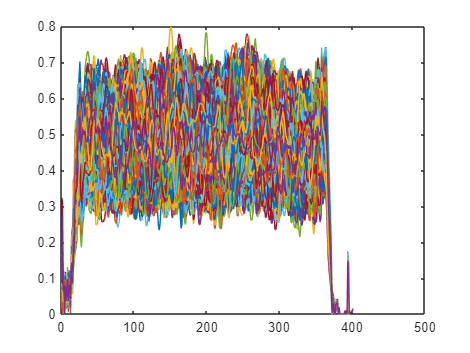

clf
plot(data_out)

clf
hold on
for i = 1:1000
    plot(data_out(:,i))
end